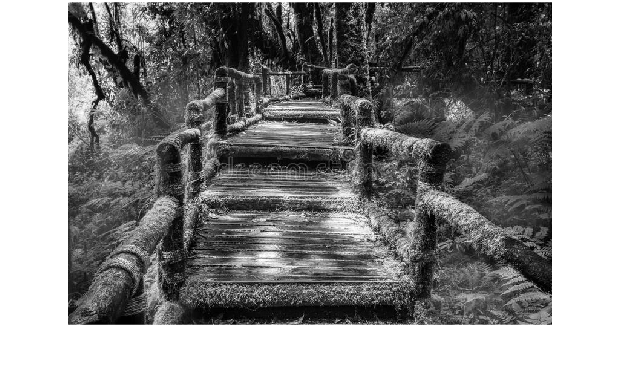

img = rgb2gray(imread('img1.jpg'));
imshow(img);

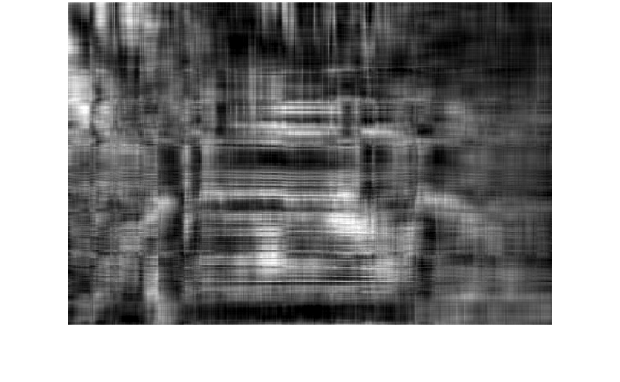

img_cmp = zeros(size(img));
[U,V,Ut] = svd(im2double(img));
for i =1:10
    img_cmp = img_cmp + (U(:,i)*V(i,i)*Ut(:,i)');
    imshow(img_cmp);
    pause(1);
end